# Evaluate and Customize Classification Models 

## Introduction

You've previously trained and evaluated classification models in the Classification Learner App. Here you'll see 

- How to reproduce the training done in the app 

- Examples of some additional training options

- How to create confusion matrices and calculate performance metrics

- How to construct ROC curves to evaluate a model at different score threshold levels

## Load data and features

Start by loading a month of taxi data and adding the toll feature using the provided function. 

taxiData = importTaxiData('yellow_tripdata_2015-01.csv');
taxiData = addWasTollPaid(taxiData);

Next, [create a categorical version](https://www.mathworks.com/help/matlab/ref/categorical.html?s_tid=srchtitle#d120e117640) of the logical variable `taxiData.WasTollPaid` to practice training models with this type of response.

taxiData.WasTollPaidCat = categorical(taxiData.WasTollPaid,[false true],["No Toll" "Toll"]); 

## Logistic Regression

### Training

The `fitglm` function can train various types of generalized linear models. The syntax to train a logistic regression model to predict the toll status is given below. When you are first going through this reading, use the default model specification of "linear". Later, you can return and try out several other options as described in the [documentation](https://www.mathworks.com/help/stats/fitglm.html?s_tid=srchtitle). 

logRegMdl = fitglm(taxiData,'linear','Distribution','binomial', ...
    "PredictorVars",[ "PickupLon" "PickupLat" "DropoffLon" "DropoffLat"],...
    "ResponseVar","WasTollPaidCat")

logRegMdl = Generalized linear regression model:
    logit(P(WasTollPaidCat='Toll')) ~ 1 + PickupLon + PickupLat + DropoffLon + DropoffLat
    Distribution = Binomial

Estimated Coefficients:
                   Estimate      SE       tStat       pValue   
                   ________    _______    ______    ___________

    (Intercept)      3107.1     24.466       127              0
    PickupLon        27.892    0.25058    111.31              0
    PickupLat        11.894    0.38804    30.651    2.5964e-206
    DropoffLon       20.499    0.24824    82.578              0
    DropoffLat     -0.39749    0.31901    -1.246        0.21276


233274 observations, 233269 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 2.74e+04, p-value = 0

When used for logistic regression, the `fitglm` function produces a model which predicts scores from 0 to 1 representing the probability of being one of the two classes in the response, instead of the response classes directly. 

scoresLogReg = predict(logRegMdl,taxiData)

scoresLogReg =     0.0308
    0.0308
    0.0608
    0.0059
    0.0087
    0.0188
    0.0084
    0.0317
    0.0226
    0.0150


In this case, the output from the model training specifies that the scores represent the probability of the response being the `Toll` class:

 

### Converting Scores to Predictions

To convert the scores to class predictions, first convert them to logical values. Then, assign a category name to logical 0 and logical 1 as shown below: 

thresholdLogReg =0.5;
predictedLogReg = scoresLogReg >= thresholdLogReg;
predictedLogReg = categorical(predictedLogReg , [false true], ["No Toll" "Toll"]) 

predictedLogReg = 233274×1 categorical array
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 


Note that it is important to assign logical `false` as `No Toll` and `true` as `Toll` in order to match the categories in the `WasTollPaid` variable.

You can tune the threshold between 0 and 1 to observe the effects on the metrics calculated next.  

### Performance Metrics 

Once you have produced the predictions, you can create a confusion matrix just like you saw in the app using the `confusionchart` function with two inputs: the true class vector first, and the predicted class vector second.  

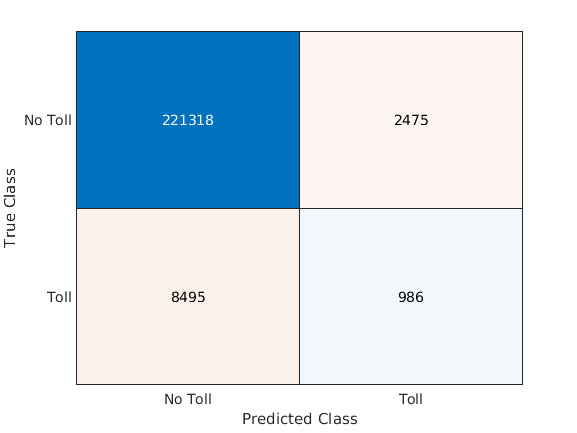

clf; 
confusionchart(taxiData.WasTollPaidCat,predictedLogReg)

To get just the matrix values, use the `confusionmat` function with the same inputs as above: 

cmLogReg = confusionmat(taxiData.WasTollPaidCat,predictedLogReg)

cmLogReg =       221318        2475
        8495         986


As you know, you can use these numbers to calculate various performance metrics for the classification model, depending which class you choose to be positive. For example, if you want the Recall (True Positive Rate) assuming that the `Toll` class is positive: 

recallTrueClass = cmLogReg(2,2)/(cmLogReg(2,2)+cmLogReg(2,1))

recallTrueClass = 0.1040

Alternatively, assuming the `No Toll` class is positive: 

recallFalseClass = cmLogReg(1,1)/(cmLogReg(1,1)+cmLogReg(1,2))

recallFalseClass = 0.9889

This process can get fairly tedious. To save you time, we have provided a custom function `cMetrics` which calculates the Precision, Recall, Fallout, Specificity, and F1-Score for each class assumed positive, as well as an average and weighted average for each metric. (This function works with multi-class classification results as well.) 

The inputs to this function are identical to those for `confusionchart` and `confusionmat` above: 

cMetrics(taxiData.WasTollPaidCat,predictedLogReg)

Accuracy = 95.30%

ans = 4×5 table
               Precision    Recall     Fallout     Specificity      F1   
               _________    _______    ________    ___________    _______

    No Toll     0.96304     0.98894       0.896        0.104      0.97582
    Toll        0.28489       0.104    0.011059      0.98894      0.15237
    Avg         0.62396     0.54647     0.45353      0.54647      0.56409
    WgtAvg      0.93547     0.95297     0.86004      0.13996      0.94235


#### ROC Curve 

Remember that the ROC curve shows the Recall and Fallout metrics for the model as functions of the score threshold value as it varies from 0 to 1. To create an ROC curve in code, first use the `perfcurve` function (see [documenation](https://www.mathworks.com/help/stats/perfcurve.html?s_tid=srchtitle)) with the model response, model scores, and choice of positive class as inputs: 

[falloutsLogReg,recallsLogReg] = perfcurve(taxiData.WasTollPaidCat,scoresLogReg,"Toll");

You can then use the output vectors for fallout and recall to plot the ROC curve itself. 

clf; 
plot(falloutsLogReg,recallsLogReg); 
xlabel("FPR (Fallout)");
ylabel("TPR (Recall)");
hold on; 

In addition to the curve, you can plot the point on the curve corresponding to a chosen threshold value. To get the coordinates of recall and fallout for a chosen threshold, you can use the `perfcurve` function again, but this time with the option `"TVals"` followed by the threshold value between 0 and 1 you're interested in. The code below uses the threshold value chosen above, so the metrics will match those in the output of `cMetrics`. 

[falloutTLogReg,recallTLogReg] = perfcurve(taxiData.WasTollPaidCat,scoresLogReg,"Toll","TVals",thresholdLogReg);
ccDot = plot(falloutTLogReg,recallTLogReg,"ro","MarkerFaceColor","r"); 

You can then add a nice title and legend to your plot with the values displayed:

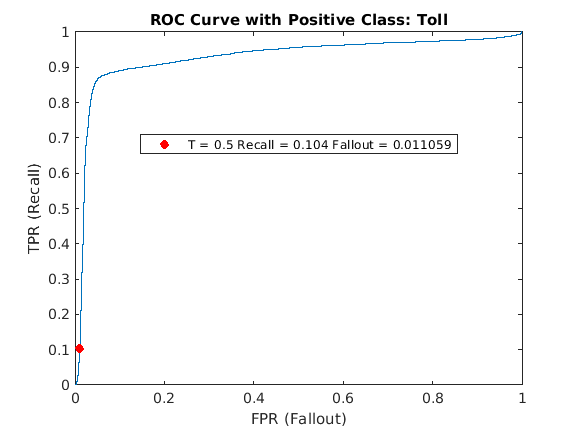

title("ROC Curve with Positive Class: Toll")
legend(ccDot, "T = " + string( thresholdLogReg ) + " Recall = " + string(recallTLogReg) + " Fallout = " + string(falloutTLogReg) ,...
    "Location","best")
hold off; 

Note that we have only constructed the ROC curve assuming the T`oll` class is positive. To obtain the ROC curve assuming the `No Toll` class is positive, you'll need to negate the score values since they are the probability of being the `Toll` class, and switch the option for which class you consider positive to `No Toll`:  

[falloutsLogReg,recallsLogReg] = perfcurve(taxiData.WasTollPaidCat,1-scoresLogReg,"No Toll");

From there, the plotting can be done in a similar way as before. Verify that the metrics again match the outputs from `cMetrics` above. 

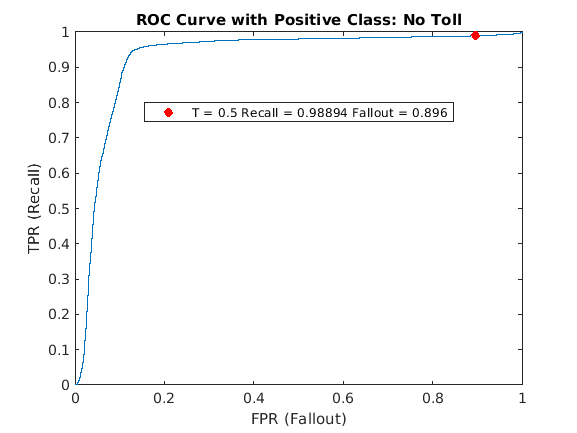

clf; 
plot(falloutsLogReg,recallsLogReg); 
xlabel("FPR (Fallout)");
ylabel("TPR (Recall)");
hold on; 
% In perfccurve, T is taken from 0->1 "towards positive class"
[falloutTLogReg,recallTLogReg] = perfcurve(taxiData.WasTollPaid,1-scoresLogReg,"false","TVals",1-thresholdLogReg);
ccDot = plot(falloutTLogReg,recallTLogReg,"ro","MarkerFaceColor","r");
title("ROC Curve with Positive Class: No Toll")
legend(ccDot, "T = " + string( thresholdLogReg ) + " Recall = " + string(recallTLogReg)+ " Fallout = " + string(falloutTLogReg)  ,...
    "Location","best")
hold off; 

## KNN

### Training

An example of training a KNN model using `fitcknn` (see [documentation](https://www.mathworks.com/help/stats/fitcknn.html?s_tid=srchtitle)) to predict whether or not a toll was paid is given below. The number of neighbors and distance weight are set up to be easily customizable. 

knnMdl = fitcknn(taxiData,"WasTollPaidCat","NumNeighbors",50,"DistanceWeight","equal",...
    "PredictorNames",[ "PickupLon" "PickupLat" "DropoffLon" "DropoffLat"],...
    "ResponseName","WasTollPaidCat")

knnMdl =   ClassificationKNN
           PredictorNames: {'PickupLon'  'PickupLat'  'DropoffLon'  'DropoffLat'}
             ResponseName: 'WasTollPaidCat'
    CategoricalPredictors: []
               ClassNames: [No Toll    Toll]
           ScoreTransform: 'none'
          NumObservations: 233274
                 Distance: 'euclidean'
             NumNeighbors: 50


  Properties, Methods


Here, note the order of the elements in the `ClassNames` property of the model:

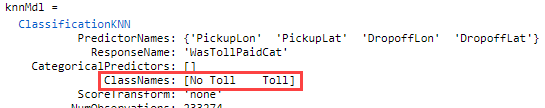

This order determines the order of the scores you will obtain next. The `predict` function with a KNN model can be used with two outputs: first is the class predictions assuming a default score threshold of 0.5, and second is a matrix with vectors representing the [confidence scores for each class](https://www.mathworks.com/help/stats/classificationsvm.resubpredict.html?s_tid=srchtitle#shared-Score). You can use either column of the scores matrix in a binary classification KNN model with a custom threshold to produce new predictions: 

thresholdKNN = 0.5; 
[predictedKNN,scoresKNN] = predict(knnMdl,taxiData)

predictedKNN = 233274×1 categorical array
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 


scoresKNN =     1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    1.0000         0
    0.9800    0.0200


### Converting Scores to Predictions 

To illustrate, choose the `No Toll` class as positive, which has scores in the first column of `scoreKNN` (see above). The process for converting the score values to class values is essentially the same as with Logistic Regression otherwise:

predKNNNoToll = scoresKNN(:,1) >= thresholdKNN;
predKNNNoToll = categorical(predKNNNoToll,[true false],["No Toll" "Toll"])

predKNNNoToll = 233274×1 categorical array
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 
     No Toll 


### Performance Metrics

Once you have produced the predictions for your chosen threshold (or just use the default predictions) the metrics are again easy to obtain using `cMetrics`: 

cMetrics(taxiData.WasTollPaidCat,predKNNNoToll)

Accuracy = 98.81%

ans = 4×5 table
               Precision    Recall      Fallout     Specificity      F1   
               _________    _______    _________    ___________    _______

    No Toll     0.99366     0.99395      0.14967      0.85033      0.99381
    Toll        0.85629     0.85033    0.0060458      0.99395       0.8533
    Avg         0.92498     0.92214     0.077857      0.92214      0.92355
    WgtAvg      0.98808     0.98812      0.14383      0.85617       0.9881


#### ROC Curve 

Construction of ROC curves follows essentially the same steps as before. The key difference being you must be careful to specify the correct column in the scores matrix for the chosen positive class: 

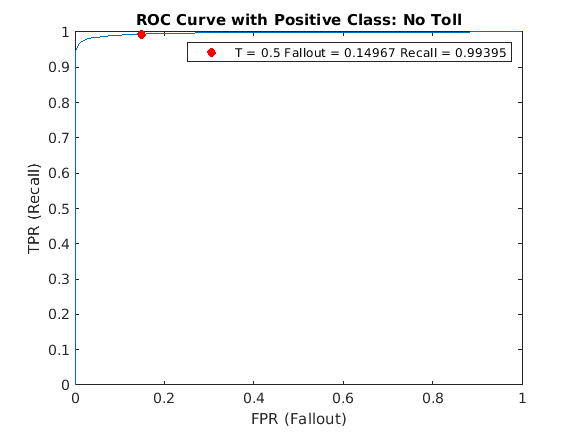

[falloutsKNN,recallsKNN] = perfcurve(taxiData.WasTollPaidCat,scoresKNN(:,1),"No Toll");
clf
plot(falloutsKNN,recallsKNN);
xlabel("FPR (Fallout)");
ylabel("TPR (Recall)");
hold on;
[falloutTKNN,recallTKNN] = perfcurve(taxiData.WasTollPaidCat,scoresKNN(:,1),"No Toll","TVals",thresholdKNN);
ccDot = plot(falloutTKNN,recallTKNN,"ro","MarkerFaceColor","r"); 
title("ROC Curve with Positive Class: No Toll")
legend(ccDot, "T = " + string(thresholdKNN) + " Fallout = " + string(falloutTKNN) + " Recall = " + string(recallTKNN) )
hold off; 

Try yourself to generate the predictions using the 2nd column in the scores matrix, and create the ROC curve assuming `Toll` is the positive class: 

## Other Model Types

To learn more about how to customize these model types in code, as well as train other classification model types, refer to the following documentation: 

[Classification Functions](https://www.mathworks.com/help/stats/referencelist.html?type=function&category=classification) 

To learn how to extract the scores and construct ROC curves for other model types, refer to the documentation for the `perfcurve` function: 

[ROC Curve Function](https://www.mathworks.com/help/stats/perfcurve.html) 

[](https://www.mathworks.com/help/stats/referencelist.html?type=function&category=classification)